# ROMI ANIMATION - ME 405

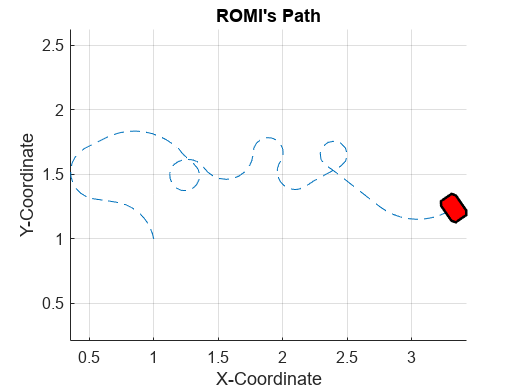

clear, clc, clf
tf = 15 ;
tspan = 0:0.1: tf;
x_0 =  [0; 1; 1; 5*pi/9];
[tout, xout, yout] = ode45(@sysEQN,tspan,x_0);

figure()
if true
    for i = 1:length(tout)
        cla
        ROMI = Romi(xout(i,2),xout(i,3),xout(i,4));
        hold on
        plot(xout(1:i,2), xout(1:i,3),'--')
        plot(ROMI(:,1), ROMI(:,2))
        fill(ROMI(:,1), ROMI(:,2),'red', LineWidth=1.5);
        xlabel("X-Coordinate")
        ylabel("Y-Coordinate")
        title("ROMI's Path")
        axis equal
        axis auto
        grid on
        pause(0.1)
        hold off
    end
end


function [xd] = sysEQN(t,x)
rw = 35e-3;
rR = 70e-3;
if t >= 0 && t < 1
    u = [10; 15];
elseif t > 2 && t < 3
    u = [20; 10];
elseif t > 4 && t < 5
    u = [20; 15];
elseif t > 6 && t <= 7
    u = [20; 5];
elseif t > 7 && t <= 8
    u = [15; 5];
elseif t > 8 && t <= 9
    u = [10; 20];   
elseif t > 9 && t <= 10
    u = [20; 5];
elseif t > 10 && t <= 11
    u = [5; 15];
elseif t > 11 && t <= 12
    u = [10; 10];     
elseif t > 12 && t <= 13
    u = [5; 25];
elseif t > 13 && t <= 14
    u = [15; 15];
elseif t > 14 && t <= 15
    u = [15; 20];
else
    u = [5; 5];
end

% R_desired = 0.6;
% V_desired = 0.25;
% 
% V_L = V_desired * (2*R_desired-2*rR)/(2*R_desired);
% V_R = V_desired * (2*R_desired+2*rR)/(2*R_desired);
% 
% w_L = V_L / rw;
% w_R = V_R / rw;
% 
% u = [w_L;w_R];

B = [rw/2,  rw/2
     rw/2 * cos(x(4)), rw/2 * cos(x(4))
     rw/2 * sin(x(4)), rw/2 * sin(x(4))
    -rw/(2*rR)       , rw/(2*rR)       ];

xd  =  B*u;
y   = [x;xd]; 
end

function R = R(th)
R  = [ cos(th) sin(th)
    -sin(th) cos(th) ];
end

function Romi = Romi(x, y, th)
Romi = [ 70  0
         70  70
         50  100 
        -50  100
        -70  70 
        -70  0
        -70 -70
        -50 -100
         50 -100
         70 -70]/1000;
Romi = Romi*R(th)+[x y];
end


% clear,clc,clf
% 
% rw = 35e-3;
% rR = 70e-3;
% 
% wR = 7.5
% wL = 4
% 
% v = rw*(wR + wL)/2
% y = rw*(wR - wL)/(2*rR)
% 
% 
% syms y v rw wR wL rR
% e1 = v == rw*(wR + wL)/2
% e2 = y == rw*(wR - wL)/(2*rR)
% 
% soln = solve([e1;e2], [wL,wR])
% rw = 35e-3;
% rR = 70e-3;
% 
% y = 0
% v = 0.2625
% 
% wR = eval(soln.wR)
% wL = eval(soln.wL)